Let us turn our attention to modulation now.

We will look at the following modulation techniques:

1) BPSK

2) QAM

3) QPSK

## 1) BPSK: Binary Phase Shift-Keying

It is an digital modulation technique.

In this technique, we transmit different phases of carrier for different values of input message.

A carrier is a high frequency sign wave in which we imbue the message for efficient transmission.

c(t) = A cos (2*pi*fc*t);

So, in BPSK, we transmit two different phases of carrier: cos(2*pi*fc*t) and cos(2*pi*fc*t + **pi**) dependin on the input bit.

Now, a good choice for most applications is to instead of transferring 1 and 0, we can transfer 1 and -1.

Output :

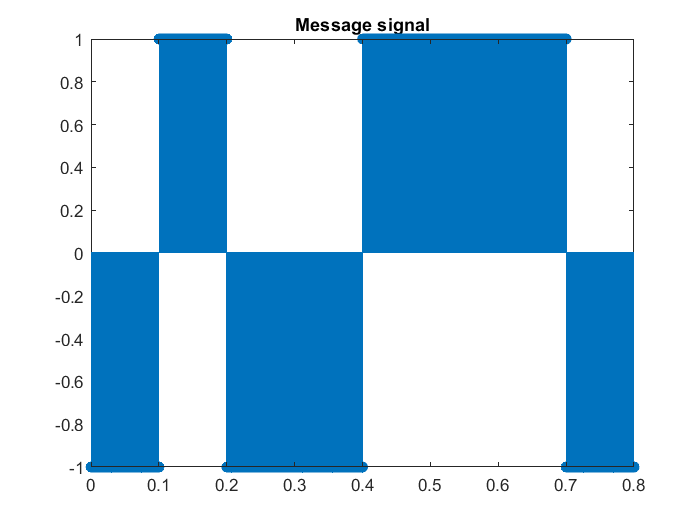

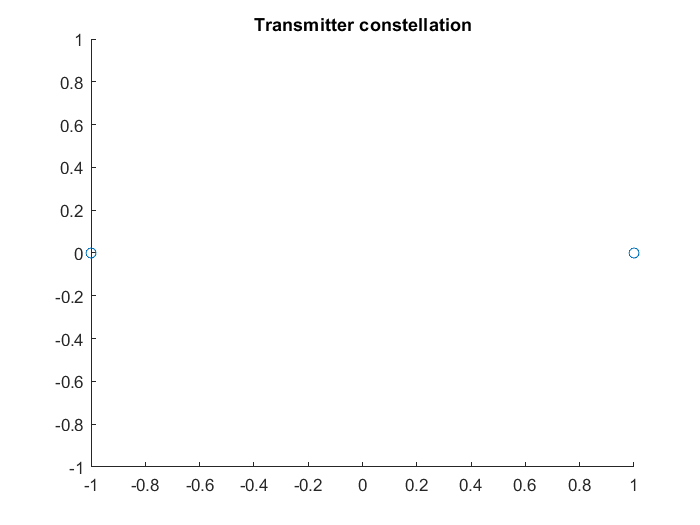

% our message signal
m = [0 1 0 0 1 1 1 0]; 

% converting 0's to -1
m = 2*m - 1;

% lets convert it to its electrical version
ta = 0.1     %pulse duration 0.1s

ta = 0.1000

dt = ta/500;  % sampling period
t = dt:dt:ta*size(m, 2); 

s = m(ceil(t/ta));
stem(t, s);
title("Message signal")

scatter(s,zeros(size(s)));
title("Transmitter constellation");


fc = 1e4    %10kHz

fc = 10000

modulated = s .* cos(2*pi*fc*t);

To check the efficacy of the modulation technique, we will add some gaussian noise with snr 10 dB.

Output :

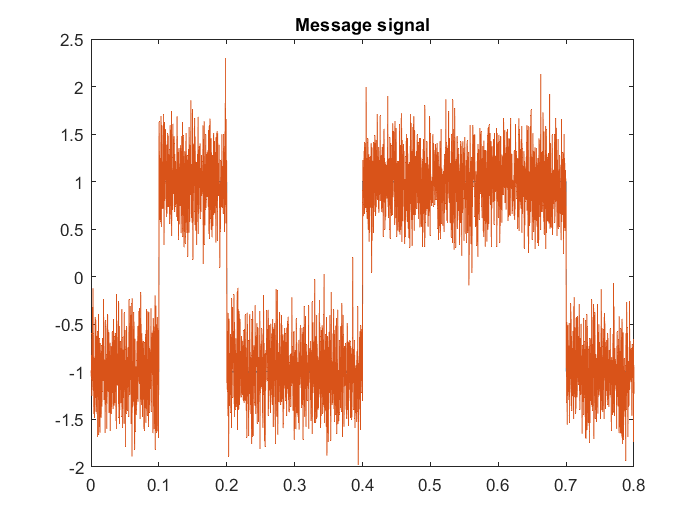

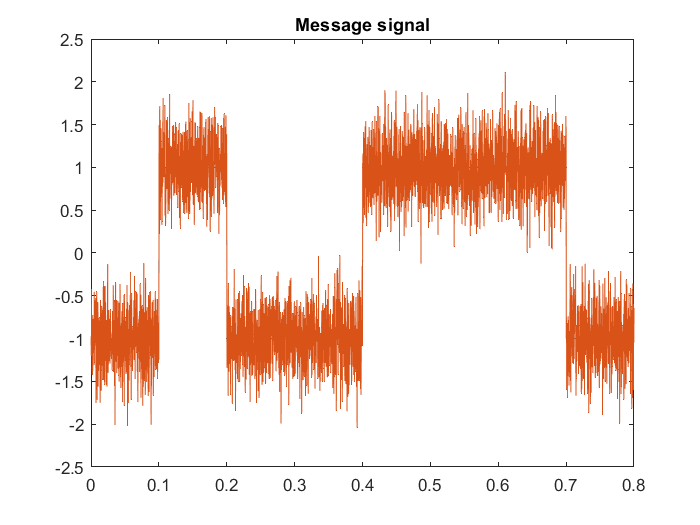

plot(t,modulated)
hold on
received = awgn(modulated, 10);
plot(t,received)
title("Message signal")
hold off

For Demodulation, we will multiply the modulated signal by the carrier and then integrate it over a single pulse duration (it is like applying a low pass filter, don't worry if you don't get it). Think of it as just a boilerplate!

Output :

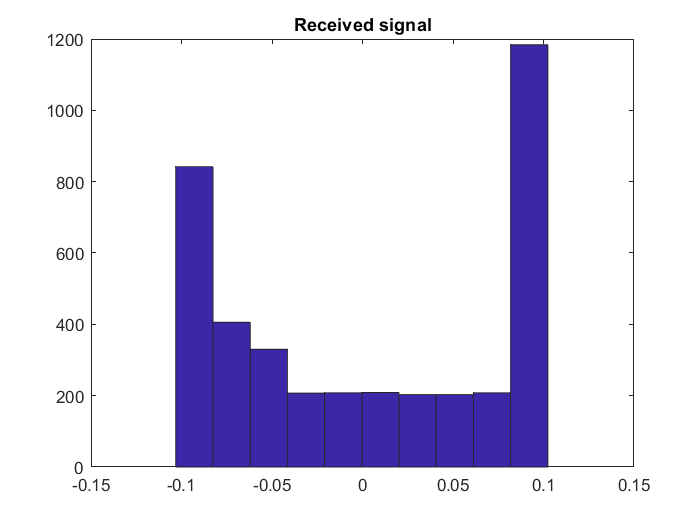

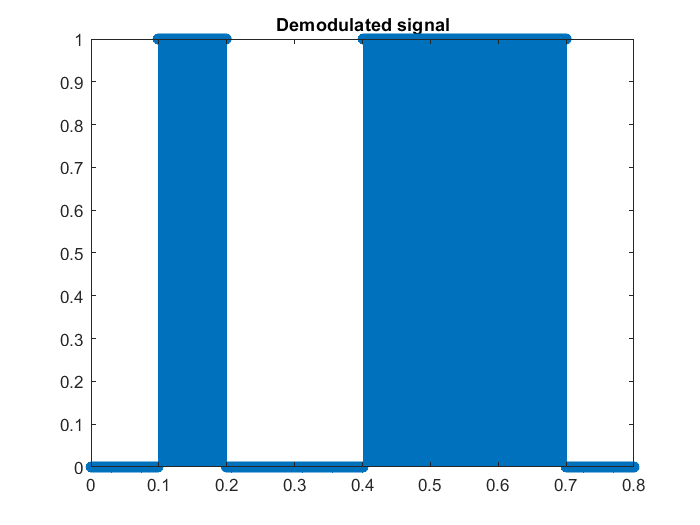

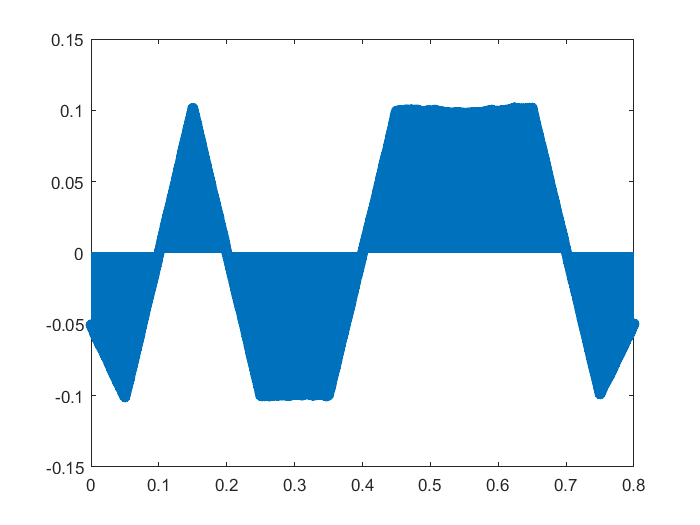

c = cos(2*pi*fc*t);
demod = received.*c;

% conv function is for summing all values in  a window
% of time from a given instant. multiply it with dt and
% we get our integrated version.
demod = conv(demod, dt*ones(1, ta/dt), 'same');
stem(t, demod)

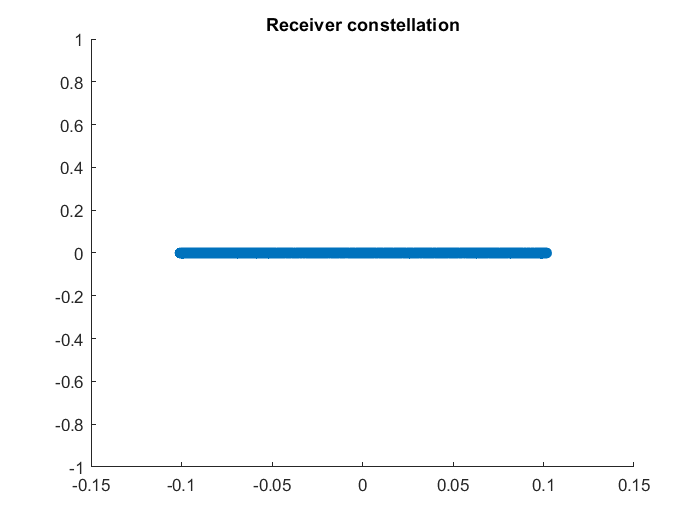

scatter(demod,zeros(size(demod)));
title("Receiver constellation");

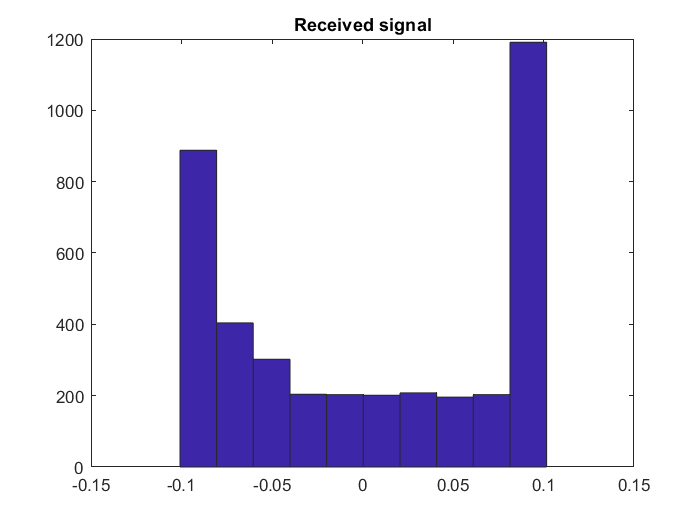

hist(demod)
title("Received signal")

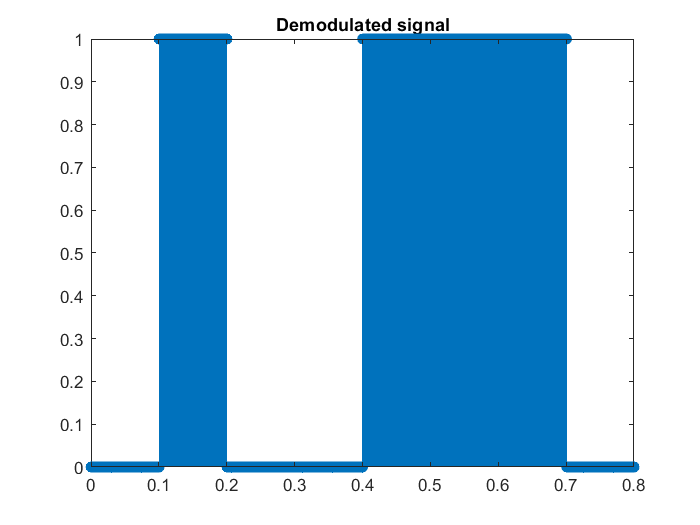

%note that the signal received is not perfect
% hence we will do some slight thresholding
demod = demod > 0;
stem(t, demod);
title("Demodulated signal")


% refer to digital.mlx
% to extract individual values we sample
% starting from the first sample at ta/2 we take a gap of ta until the end.
sampling_times = ta/2:ta:ta*size(m, 2)

sampling_times =     0.0500    0.1500    0.2500    0.3500    0.4500    0.5500    0.6500    0.7500



% in actual vector s, the time 't' corresponds to the index t/dt.
m_reconstructed = s(floor(sampling_times/dt))

m_reconstructed =     -1     1    -1    -1     1     1     1    -1



% note that the message is -1 for 0. we can simply threshold it again
m_reconstructed = m_reconstructed > 0

m_reconstructed = 1×8 logical array
   0   1   0   0   1   1   1   0


## 2) QAM: Quadrature Amplitude Multiplexing

It is used to transmit two different signals using a single carrier.

How is it done?

The first signal is multiplied to a sine carrier and the second to a cosine carrier.

While demodulating, if we do the same thing as above in BPSK, use a cosine carrier, then the second signal is obtained. With a sine carrier the first signal will be obtained.

Let us see the following program for better clarity.

Output:

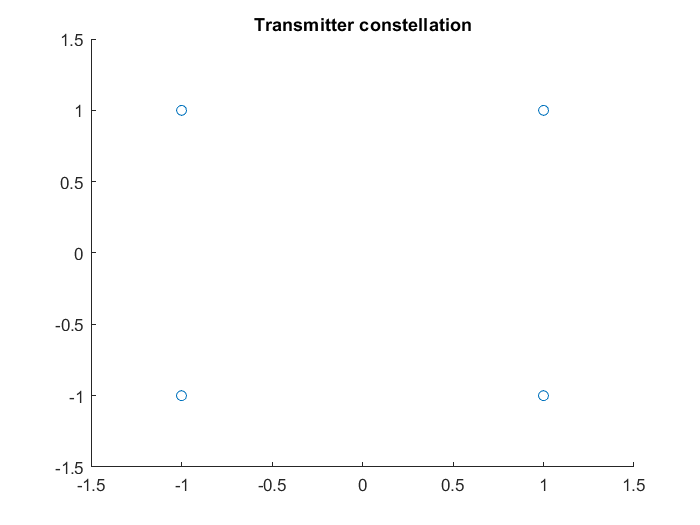

% carrier frequency
fc = 1e4  %10kHz

fc = 10000


% pulse duration
ta = 1e-3  % 0.1ms

ta = 1.0000e-03


% no of samples in one pulse
ns = 1000

ns = 1000


% sampling period; 1000 samples for one pulse
dt = ta/ns

dt = 1.0000e-06

 
% the message signals
m1 = [1 0 1 0 1 0]

m1 =      1     0     1     0     1     0


m2 = [0 0 1 1 0 0]

m2 =      0     0     1     1     0     0



% again shift the signals:
m1 = 2*m1-1

m1 =      1    -1     1    -1     1    -1


m2 = 2*m2-1

m2 =     -1    -1     1     1    -1    -1


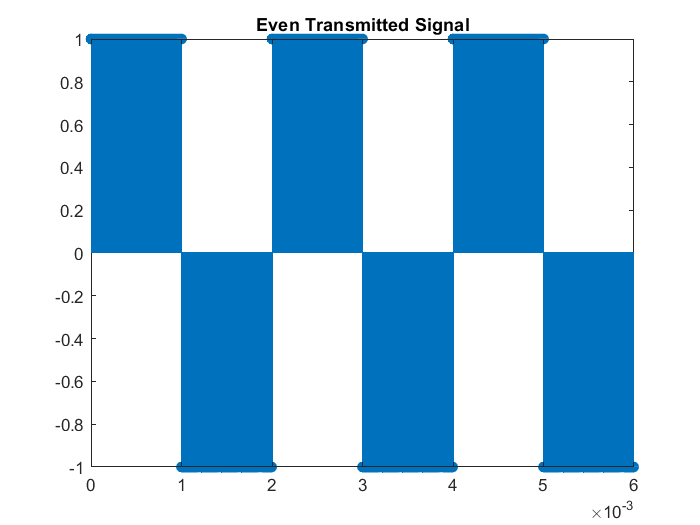


% time values
t = dt:dt:ta*size(m1, 2);

% lets make physical versions of m1 and m2
s1 = m1(ceil(t/ta));
s2 = m2(ceil(t/ta));

stem(t, s1);
title("Even Transmitted Signal")

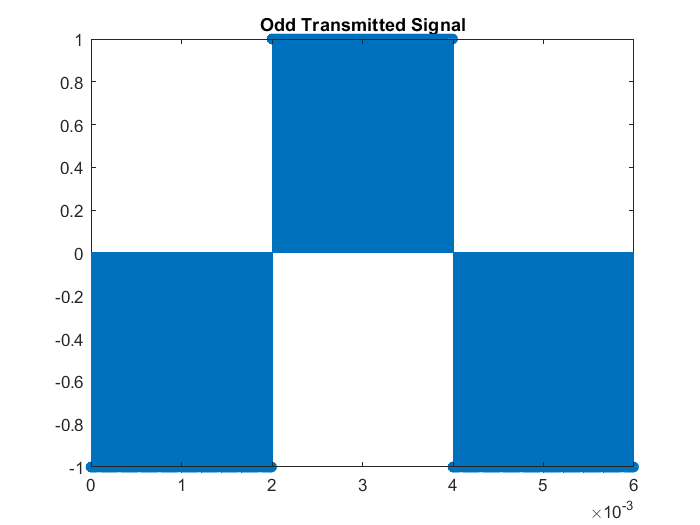

stem(t, s2);
title("Odd Transmitted Signal")


scatter(s1,s2);
xlim([-1.5,1.5])
ylim([-1.5,1.5])
title("Transmitter constellation");


% cosine part:
cosine = s1 .* cos(2*pi*fc*t);

% sine part:
sine = s2 .* sin(2*pi*fc*t);

modulated = cosine + sine;

Now, demodulation,

Output :

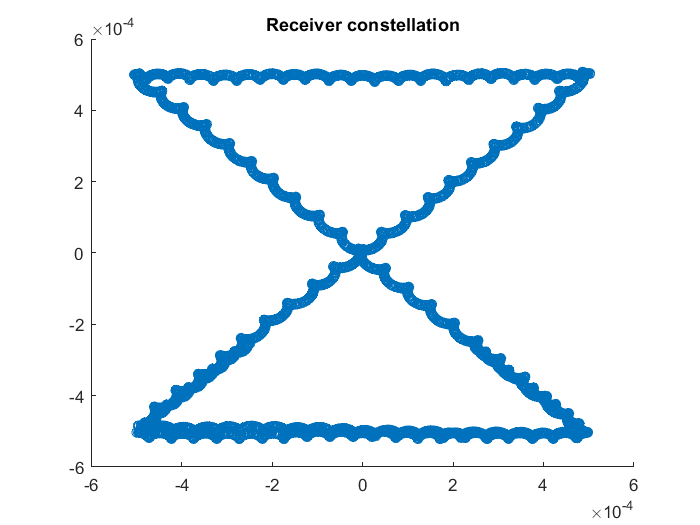

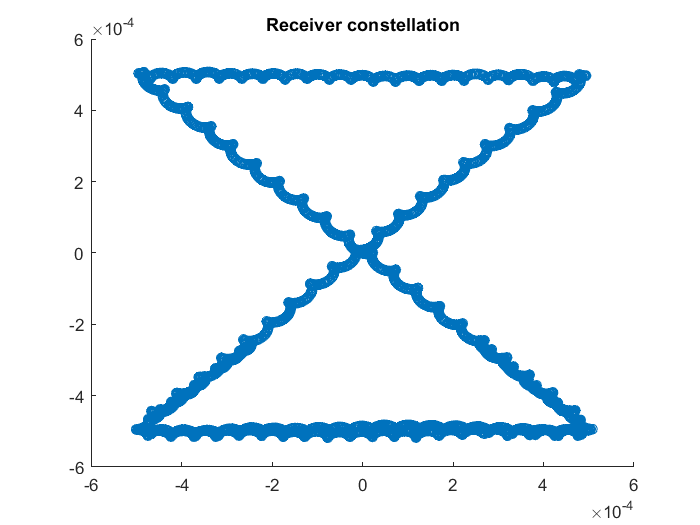

% add 10dB noise:
received = awgn(modulated, 10);

% multiplying modulated signal by cos(2*pi*fc*t)
sig1 = received .* cos(2*pi*fc*t);

% multiplying modulated signal by sin(2*pi*fc*t)
sig2 = received .* sin(2*pi*fc*t);

% now we will apply the filter (conv):
sig1 = conv(sig1, ones(1, ns)*dt, 'same');
sig2 = conv(sig2, ones(1, ns)*dt, 'same');

%plot(t,sig1);
%plot(t,sig2);

scatter(sig1,sig2);
title("Receiver constellation");

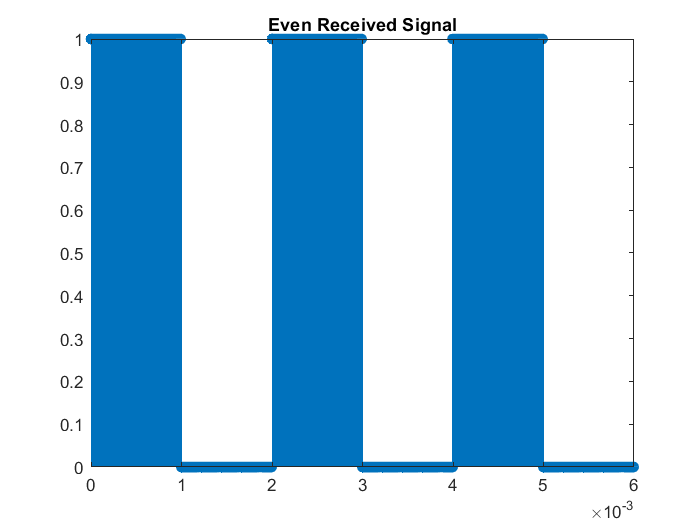


% threshold as before
sig1 = sig1 > 0;
sig2 = sig2 > 0;

stem(t, sig1);
title("Even Received Signal")

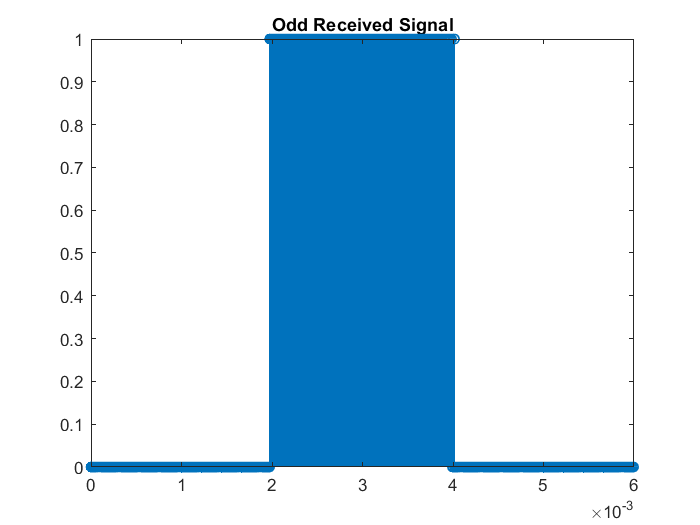

stem(t, sig2);
title("Odd Received Signal")

% sample
sampling_times = ta/2:ta:ta*size(m1, 2);

m1_reconstructed = sig1(floor(sampling_times/dt));
m1_reconstructed = m1_reconstructed > 0

m1_reconstructed = 1×6 logical array
   1   0   1   0   1   0



m2_reconstructed = sig2(floor(sampling_times/dt));
m2_reconstructed = m2_reconstructed > 0

m2_reconstructed = 1×6 logical array
   0   0   1   1   0   0


## 3) QPSK: Quadrature Phase Shift-Keying

It is an extension of BPSK. You can guess that BPSK used two phases (binary). So, QPSK will use four phases (quad-).

How does it use four phases?

Suppose we had a message 00 01 10 11.

In qpsk, we take two bits at a time and we transmit a particular phase for a single pulse duration.

What we mean to say is that

for 00, we will transmit a phase of an angle, say phi.

for 01, phi + 90 deg

for 10, phi + 180 deg

for 11, phi + 270 deg.

the same phase carrier exists for the duration of both the bits.

One easier way to describe this modulation scheme is that, we take even and odd bit of messages separately and double their duration. Say, me are the bits at even places (2nd bit, 4th bit and so on) and mo are the odd bits.

Eg: [00 01 10 11]

here me = [0 1 0 1] and mo = [0 0 1 1]

me = [-1 1 -1 1]

mo = [-1 -1 1 1]

again we will write -1 in place of 0's

modulated signal = me*cos(2*pi*fc*t) + mo * sin(2*pi*fc*t);

In this case phi = phase when 00 is transmitted (-1 -1) effectively 

which is -cos(2pifct) - sin(2pifct) =  - sqrt(2) * cos(2pifct - 45 deg) 

                                                    = sqrt(2) * cos(2pifct + 135 deg)

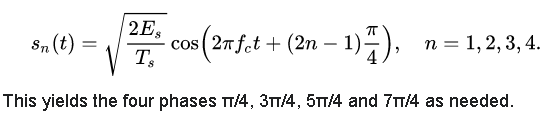

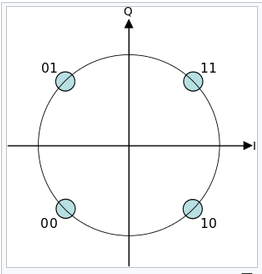

This form is similar to QAM and we can use the methods learned their in this.

QPSK is superior to BPSK because it reduces the data rate (half time required for transmitting the signal) but it increases the BER (bit error rate)

BER is the probability that a single bit will be in error due to noise in the channel.

Let's implement it

m = [0 0 0 1 1 0 0 1 1 0]

m =      0     0     0     1     1     0     0     1     1     0


m = 2*m - 1

m =     -1    -1    -1     1     1    -1    -1     1     1    -1



% you can manually loop and assign the values to me and mo but this is fast
me = m(2:2:end)

me =     -1     1    -1     1    -1


mo = m(1:2:end)

mo =     -1    -1     1    -1     1



% The rest code is same as QAM just the duration is halfed. only t changes

ta = 1e-3

ta = 1.0000e-03

ns = 500

ns = 500

dt = ta/ns

dt = 2.0000e-06

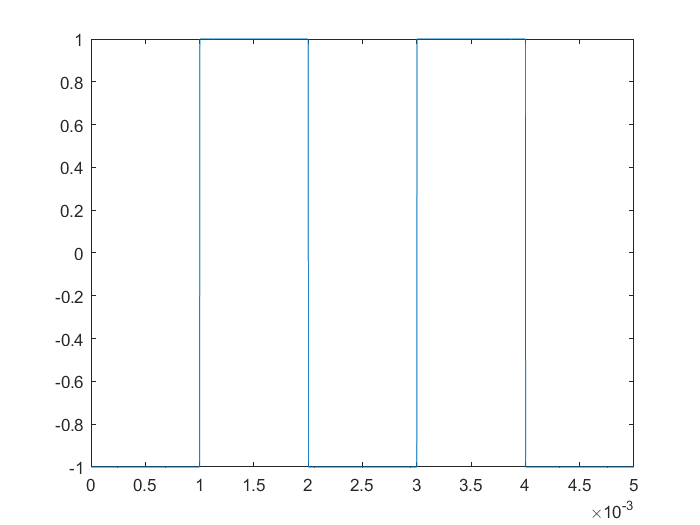

% time values note that instead of size of m, we have size of me which is half
t = dt:dt:ta*size(me, 2);

% lets make physical versions of m1 and m2
s1 = me(ceil(t/ta));
s2 = mo(ceil(t/ta));

plot(t, s1);

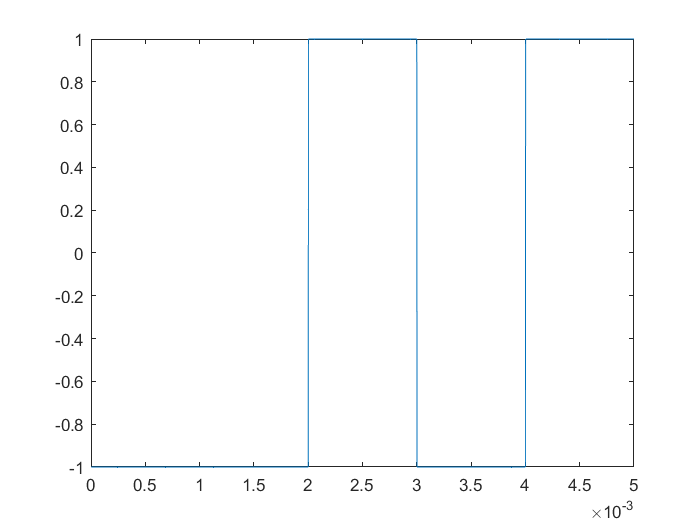

plot(t, s2);


% cosine part:
cosine = s1 .* cos(2*pi*fc*t);

% sine part:
sine = s2 .* sin(2*pi*fc*t);

modulated = cosine + sine;


Now, demodulation,

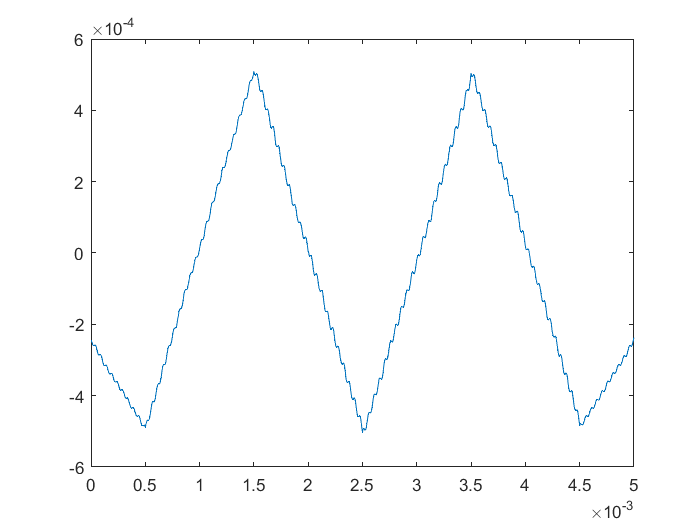

% add 20dB noise:
received = awgn(modulated, 10);

% multiplying modulated signal by cos(2*pi*fc*t)
sig1 = received .* cos(2*pi*fc*t);

% multiplying modulated signal by sin(2*pi*fc*t)
sig2 = received .* sin(2*pi*fc*t);

% now we will apply the filter (conv):
sig1 = conv(sig1, ones(1, ns)*dt, 'same');
sig2 = conv(sig2, ones(1, ns)*dt, 'same');
plot(t, sig1);

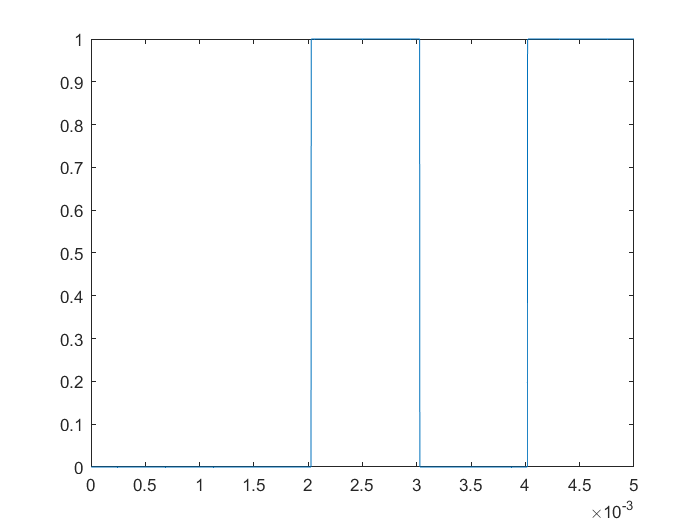

% threshold as before
sig1 = sig1 > 0;
sig2 = sig2 > 0;

plot(t, sig2);


% sample
sampling_times = ta/2:ta:ta*size(me, 2);

m1_reconstructed = sig1(floor(sampling_times/dt));
m1_reconstructed = m1_reconstructed > 0

m1_reconstructed = 1×5 logical array
   0   1   0   1   0



m2_reconstructed = sig2(floor(sampling_times/dt));
m2_reconstructed = m2_reconstructed > 0

m2_reconstructed = 1×5 logical array
   0   0   1   0   1



% combining them,
% odd places
m_reconstructed = [ m2_reconstructed ; m1_reconstructed]; 
% even places
m_final = m_reconstructed(:)';

m_final

m_final = 1×10 logical array
   0   0   0   1   1   0   0   1   1   0


## **QPSK vs QAM**

## Key Differences Between QAM and QPSK

- The spectral width of QPSK is wider than that of QAM.

- QPSK conveys 2-bit simultaneously while in case of QAM the number of bits depends on the type of QAM such as 16 QAM, 32 QAM, 64 QAM, 128  QAM, 256 QAM conveys 4, 5, 6, 7, 8 bits respectively.

- The performance of QPSK is superior to QAM.

- The bit error rate of QAM is high as compared to QPSK.

**Phase Shift Keying PSK**

Any number of phases may be used to construct a PSK constellation but  8-PSK is usually the highest order PSK constellation deployed. With more than 8 phases, the error-rate becomes too high and there are better,  though more complex, modulations available such as [quadrature amplitude modulation](https://en.wikipedia.org/wiki/Quadrature_amplitude_modulation) (QAM). Although any number of phases may be used, the fact that the  constellation must usually deal with binary data means that the number  of symbols is usually a power of 2 to allow an integer number of bits  per symbol. 

**Quadrature Amplitude Multiplexing QAM**

Quadrature amplitude theory states that both amplitude and phase change within a QAM signal.

As there are two RF signals that can be modulated, these are referred to as the I - In-phase and Q - Quadrature signals.

The I and Q signals can be represented by the equations below: 

*I*=*A*cos(Ψ) and *Q*=*A*sin(Ψ)

It can be seen that the I and Q components are represented as cosine  and sine. This is because the two signals are 90° out of phase with one  another.

Using the two equations it is possible to express the signal as:.

cos(*α*+*β*)=cos(*α*)cos(*β*)−sin(*α*)sin(*β*)

Using the expression A cos(2πft + Ψ) for the carrier signal.

*A*cos(2*π**f**t*+Ψ)=*I*cos(2?*f**t*)−*Q*sin(2*π**f**t*)

Where f is the carrier frequency.

This expression shows the resulting waveform is a periodic signal for which the phase can be adjusted by changing the amplitude either or  both I and Q.

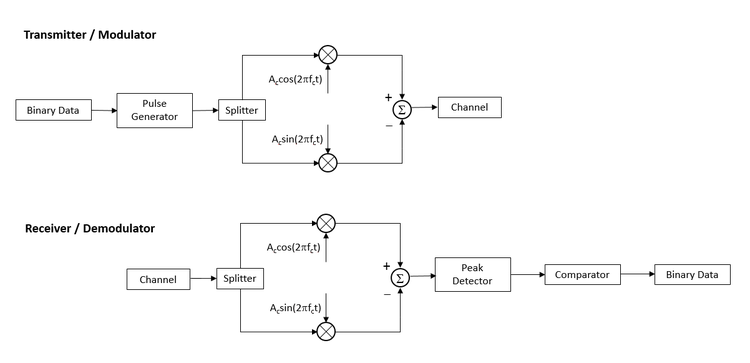

The transmitted signal is created by adding the two carrier waves  together. At the receiver, the two waves can be coherently separated  (demodulated) because of their orthogonality property.